# Electophysiological records analysis script

## Clear workspace and close all the figures, then upload demo_data file

abfload(), pvpmod() from (https://www.mathworks.com/matlabcentral/fileexchange/22114-fcollman-abfload)

clear all
close all
clc

[Full_data, si1] = abfload('demo_data.abf');

** abfload
opening demo_data.abf..
data were acquired in waveform fixed-length mode (clampex only)



Time = 0:(si1/1000):(length(Full_data)-1)*(si1/1000);
Time = Time';

## Extract traces after 1, 4, 5 stimuli and resistance drom recording


Combined_1st = [];
n = 1;
for i = 1:4:29
    Combined_1st(:, n) = Full_data(:, 1, i);
    n = n + 1;
end

Combined_1_4st = [];
n = 1;
for i = 2:4:29
    Combined_1_4st(:, n) = Full_data(:, 1, i);
   	n = n + 1;
end

Combined_1_5st = [];
n = 1;
for i = 3:4:29
    Combined_1_5st(:, n) = Full_data(:, 1, i);
    n = n + 1;
end

Current_Resistance_Combined = [];
n = 1;
for i =4:4:29
    Current_Resistance_Combined(:, n) = Full_data(:, 1, i);
    n = n + 1;
end

Create an array contained all trace

Combined_all = []


Combined_all =

     []



n = 1;
for i = 1:1:29
    Combined_all(:, n) = Full_data(:, 1, i);
    n = n + 1;
end

Create plots based on available data

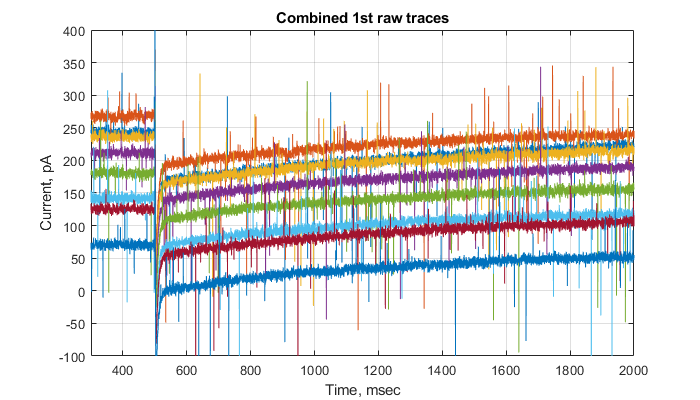

figure('position', [300 200 700 400]);
plot(Time, Combined_1st);
axis([300, 2000, -100, 400])
title('Combined 1st raw traces');
ylabel('Current, pA');
xlabel('Time, msec');
set(gcf,'PaperPositionMode','auto');
grid on;

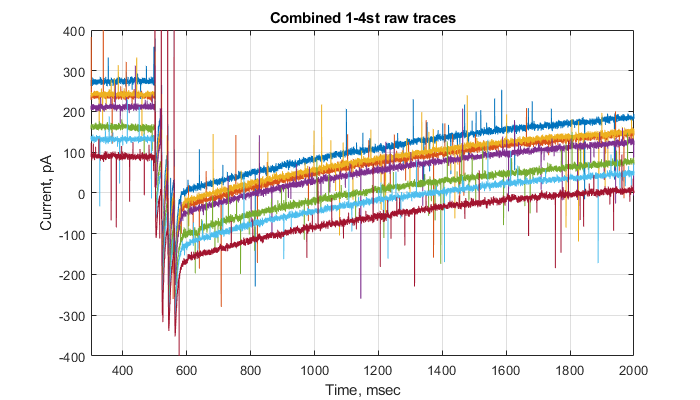

figure('position', [300 200 700 400]);
plot(Time, Combined_1_4st);
axis([300, 2000, -400, 400])
title('Combined 1-4st raw traces');
ylabel('Current, pA');
xlabel('Time, msec');
set(gcf,'PaperPositionMode','auto');
grid on;

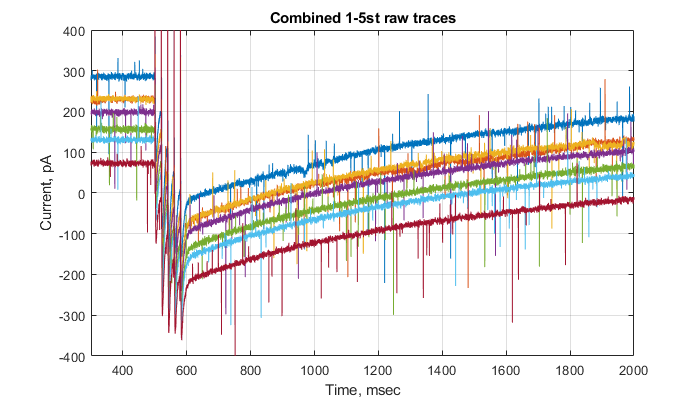

figure('position', [300 200 700 400]);
plot(Time, Combined_1_5st);
axis([300, 2000, -400, 400])
title('Combined 1-5st raw traces');
ylabel('Current, pA');
xlabel('Time, msec');
set(gcf,'PaperPositionMode','auto');
grid on;    

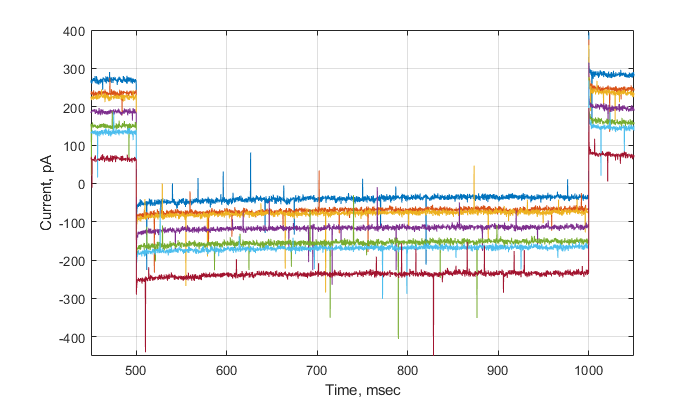

figure('position', [300 200 700 400]);
plot(Time, Current_Resistance_Combined);
axis([450, 1050, -450,400])
ylabel('Current, pA');
xlabel('Time, msec');
set(gcf,'PaperPositionMode','auto');
grid on;   

## Baseline offset

For baseline offseting script calculates mean at the beginning of the trace and subtracts it from each trace

BLstart = 1;
BLend = 2450; 

for i = 1:size(Combined_1st, 2)%% BL for 1 st
    BLCombined_1st(i) = mean(Combined_1st(BLstart:BLend, i));
    Combined_1st_Offset(:, i) = Combined_1st(:, i) - BLCombined_1st(i);
end

for i = 1:size(Combined_1_4st, 2)%% BL for 4 st
    BLCombined_1_4st(i) = mean(Combined_1_4st(BLstart:BLend, i));
    Combined_1_4st_Offset(:, i) = Combined_1_4st(:, i) - BLCombined_1_4st(i);
end
for i = 1:size(Combined_1_5st, 2)%% BL for 5 st
    BLCombined_1_5st(i) = mean(Combined_1_5st(BLstart:BLend, i));
    Combined_1_5st_Offset(:, i) = Combined_1_5st(:, i) - BLCombined_1_5st(i);
end

for i = 1:size(Combined_all, 2) %% BL check for all traces
    BLCombined_all(i) = mean(Combined_all(BLstart:BLend, i));
    Combined_all_Offset(:, i) = Combined_all(:, i) - BLCombined_all(i);
end

Create plots describing baseline offset

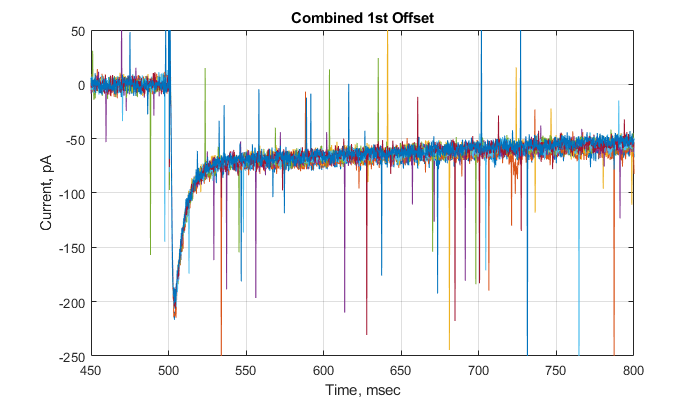

figure('position', [300 200 700 400]);
plot(Time, Combined_1st_Offset);
axis([450, 800, -250, 50])
title('Combined 1st Offset');
ylabel('Current, pA');
xlabel('Time, msec');
set(gcf,'PaperPositionMode','auto');
grid on;  

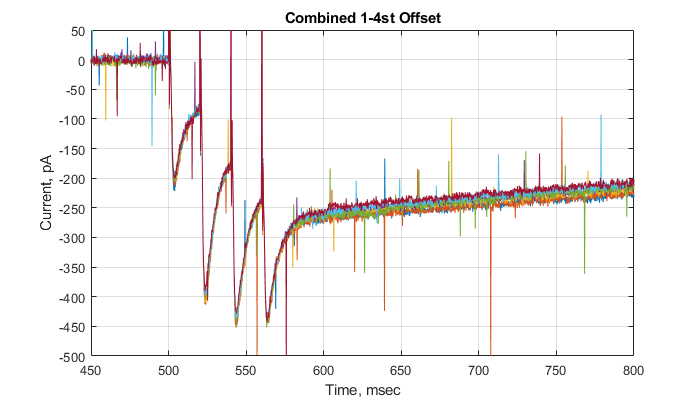

figure('position', [300 200 700 400]);
plot(Time, Combined_1_4st_Offset);
axis([450, 800, -500, 50])
grid on;
title('Combined 1-4st Offset');
ylabel('Current, pA');
xlabel('Time, msec');

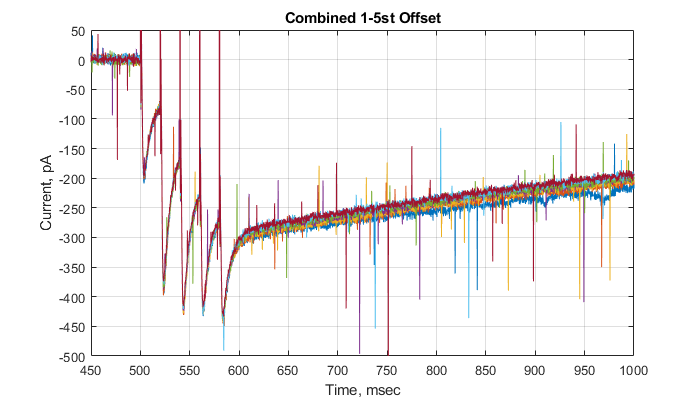

figure('position', [300 200 700 400]);
plot(Time, Combined_1_5st_Offset);
axis([450, 1000, -500, 50])
grid on;
title('Combined 1-5st Offset');
ylabel('Current, pA');
xlabel('Time, msec');

## *TRANSPORTERS SUBSTRACTION*

The current in response to the fifth(1-5) stimulus was obtained by subtracting the response to 4 stimuli from the current evoked by 5 stimuli. IGluT was recorded in the presence of 25 mM NBQX, 50 mM D-AP5, and 100 mM picrotoxin, which blocked AMPA, NMDA, and GABAA receptors, respectively.

Combined_1st_Offset_Average=mean(Combined_1st_Offset, 2);
Combined_1_4st_Offset_Average=mean(Combined_1_4st_Offset, 2);
Combined_1_5st_Offset_Average=mean(Combined_1_5st_Offset, 2);
Transporter_1 = Combined_1st_Offset_Average;
Transporter_5 = Combined_1_5st_Offset_Average - Combined_1_4st_Offset_Average; 

Shift transporter 5 to overlay stimuli response time and apply the Savitzky-Golay filter

Transporter_5 = Transporter_5(400:19999);
Transporter_5 = sgolayfilt(Transporter_5, 3, 11);

Transporter_1 = Transporter_1(1:19600);
Transporter_1 =  sgolayfilt(Transporter_1,3, 11);

Time_transporter = Time(1:19600);


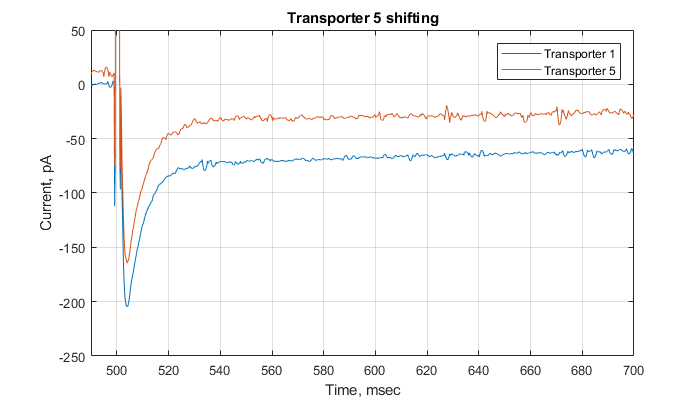

figure('position', [300 200 700 400]);
plot(Time_transporter, Transporter_1, Time_transporter, Transporter_5);
grid on;
title('Transporter 5 shifting');
axis([490, 700, -250, 50])
ylabel('Current, pA');
xlabel('Time, msec');
legend('Transporter 1', 'Transporter 5');

## *TRANSPORTER 1 AMPLITUDE MEASURE*   

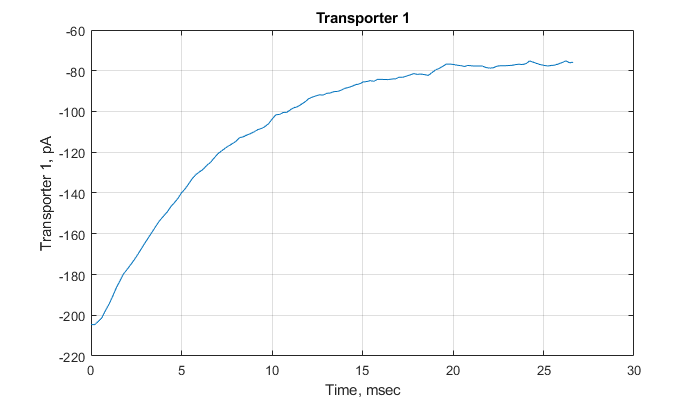

t_start = 2525; 
t_end   = 2590;

[minTransporter_1_amplitude,NminTransporter_1] = min(Transporter_1(t_start:t_end ));% find the amplitude

t_start = 2517; 
t_end   = 2650;

s_T1 = size(Transporter_1(t_start:t_end), 1);
TimeDecayTransporter_1_NORM = 0:(si1/1000):(s_T1-1)*(si1/1000);
TimeDecayTransporter_1 = TimeDecayTransporter_1_NORM';
Transporter_1_Fit = Transporter_1(t_start:t_end);

figure('position', [300 200 700 400]);
plot(TimeDecayTransporter_1, Transporter_1_Fit);
title('Transporter 1');
grid on;
ylabel('Transporter 1, pA');
xlabel('Time, msec');

## *5 TRANSPORTER AMPLITUDE MEASURE* 

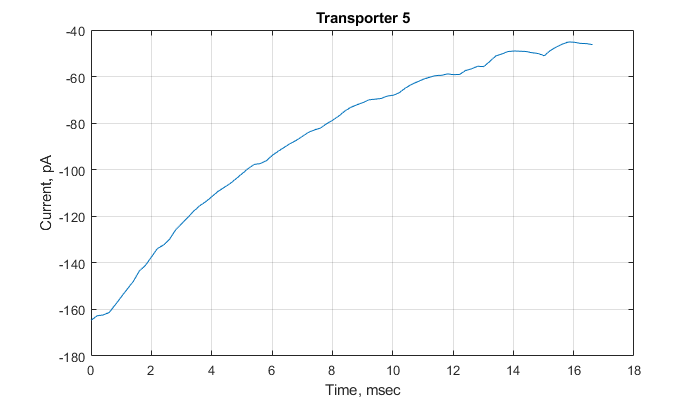

t_start = 2910; 
t_end   = 3200;

[minTransporter_5_amplitude,NminTransporter_5] = min(Transporter_5(t_start:t_end ));% find the amplitude

t_start = 2517; 
t_end   = 2600;
s_T1 = size(Transporter_5(t_start:t_end), 1);
TimeDecayTransporter_5_NORM = 0:(si1/1000):(s_T1-1)*(si1/1000);
TimeDecayTransporter_5 = TimeDecayTransporter_5_NORM';
Transporter_5_Fit = Transporter_5(t_start:t_end);

plot(TimeDecayTransporter_5, Transporter_5_Fit) ;
grid on;
title('Transporter 5');
ylabel('Current, pA');
xlabel('Time, msec');                

##  *TRANSPORTER 1 DECAY TIME AND AMPLITUDE MEASURE*

Calculate decay time as exponential fuction. 

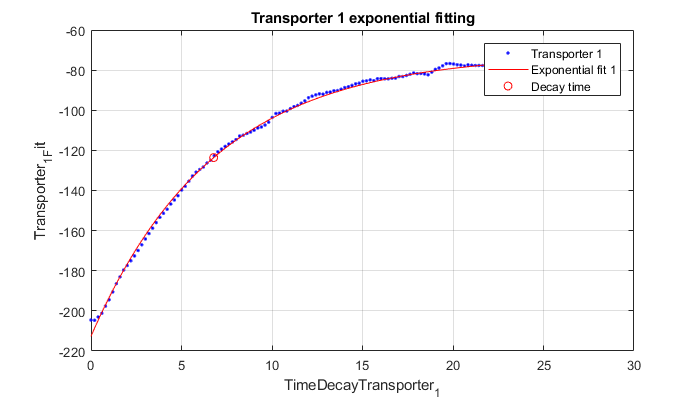

[xData, yData] = prepareCurveData( TimeDecayTransporter_1, Transporter_1_Fit);

% Set up fittype and options.
ft = fittype( 'a*exp(-b*x)+c', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Algorithm = 'Levenberg-Marquardt';
opts.Display = 'Off';
opts.StartPoint = [0.8002804688888 0.141886338627215 0.421761282626275];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );
TRANSPORTER_Tay_decay_1st=1/fitresult.b;

% Plot fit with data.
figure('position', [300 200 700 400]);
h = plot( fitresult, xData, yData);
hold on;
plot(1/fitresult.b,fitresult.a*exp(-1)+fitresult.c, 'ro')
legend( 'Transporter 1', 'Exponential fit 1', 'Decay time');
title('Transporter 1 exponential fitting');
xlabel ('TimeDecayTransporter_1')
ylabel ('Transporter_1_Fit')
grid on

##  *TRANSPORTER 5 DECAY TIME AND AMPLITUDE MEASURE*

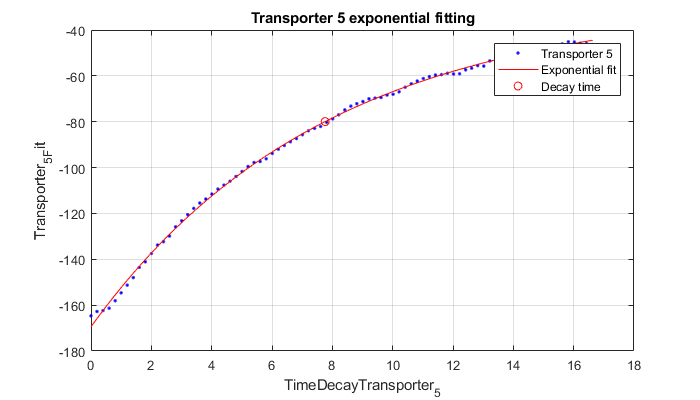

[xData, yData] = prepareCurveData( TimeDecayTransporter_5, Transporter_5_Fit );

% Set up fittype and options.
ft = fittype( 'a*exp(-b*x)+c', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Algorithm = 'Levenberg-Marquardt';
opts.Display = 'Off';
opts.StartPoint = [0.655740699156587 0.0357116785741896 0.849129305868777];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );
% Plot fit with data.
figure('position', [300 200 700 400]);
h = plot( fitresult, xData, yData);
hold on;
plot(1/fitresult.b,fitresult.a*exp(-1)+fitresult.c, 'ro')
legend( 'Transporter 5', 'Exponential fit', 'Decay time');
title('Transporter 5 exponential fitting');
xlabel ('TimeDecayTransporter_5')
ylabel ('Transporter_5_Fit')
grid on